

nt = 500;
xc = [0 5 10 15 20 25 30 35 40 45];
yc = [55 60 58 54 55 60 54 57 52 49];

min = xc(1)

min = 0

max = xc(end)

max = 45

xt = min:(max-min)/nt:max;

nc = 10;

vmoy = mean(yc)

vmoy = 55.4000

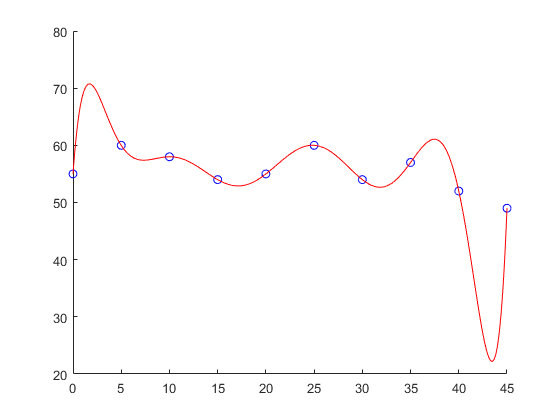


hold on 
plot(xc, yc,  "LineStyle","none", "Color", [0 0 1], "Marker","o")

resultat = zeros(1, nt);

for k = 1:nt+1
    accSomme = 0;
    for i = 1:nc
        accMul = 1;
        for j = 1:nc
            if(i == j)
                continue;
            end
            accMul = accMul * ((xt(k) - xc(j)) / (xc(i) - xc(j)));
        end
        accSomme = accSomme  + accMul * yc(i);
    end
    resultat(k) = accSomme;
end

plot(xt, resultat,  "LineStyle","-", "Color", [1 0 0])


clf 
hold on 
% INTERPL1 % 
t2point5 = interp1(xc, yc, 2.5, "spline");
plot(xc, yc,  "LineStyle","none", "Color", [0 0 1], "Marker","o")

 yt = interp1(xc, yc, 2.5, "pchip")

yt = 58.5625

% plot(xt, yt)
 yt = interp1(xc, yc, 2.5, "spline")

yt = 58.6500

% plot(xt, yt)
yt = interp1(xc, yc, 2.5, "makima")

yt = 58.4950

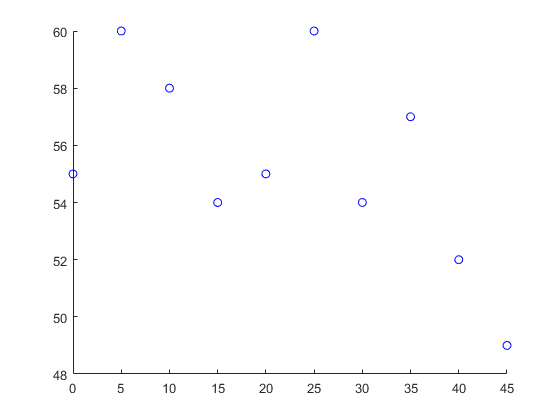

plot(xt, yt)